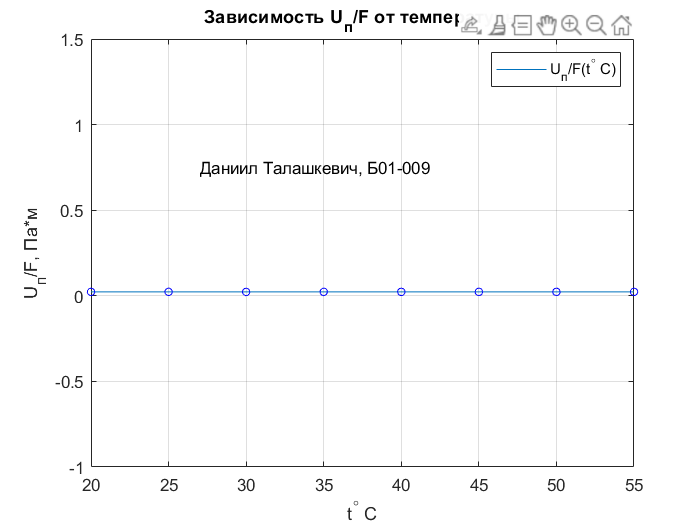

file     = importdata('main.ods');
x = file.data(:, 1);
y = [0.023 0.023 0.023 0.023 0.023 0.023 0.023 0.023];

x1 = x(1:7:8, :);
y1 = y(1:7:8);
fg1 = figure;
plot(x1, y1, '-');
hold on;
for k = 1:8
    plot(x(k, :), y(k), 'bo', 'MarkerSize', 4.5);
    set(fg1, 'visible', 'on');
    hold on;
end
grid on;
legend('U_п/F(t^\circ C)');
xlabel('t^\circ C');
ylabel('U_п/F, Па*м');
title('Зависимость U_п/F от температуры');
text(27, 0.75,'Даниил Талашкевич, Б01-009');
saveas(fg1, 'graph4', 'png');